# Deep Learning mit MATLAB

% Die MATLAB Deep LEarning Toolbox stellt einige Funktionen zum Arbeiten mit Tiefen NEuronalen Netzen zur Verfügung.
% Stellen Sie sicher, das der Arbeitspfad richtig eingestellt ist, da sonst
% die Bilder nicht gefunden werden kann. 

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(filename)


## Daten Laden und Data Store erstellen

filename = filename + "\Trainingsdaten\AusgeschnittenFürTraining\TrainingsdatenSatz30Schild1";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 2×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder               3017 
    Geschwindigkeitsbegrenzung_30     337 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 337


% img = read(imdsZahlen);
% figure;
% imshow(img)
% img = readimage(imdsZahlen, 1650);
% figure;
% imshow(img)
% size(img)


## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(imdsSchilder, 0.8, "randomized");

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([200, 200, 3])
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(2) 
    softmaxLayer
    classificationLayer
];


% %komplexes modell
% layers = [
%     imageInputLayer([200 200 3], "Name", "imageinput")
%     convolution2dLayer([3 3], 32, "Name", "conv", "Padding", "same")
%     reluLayer("Name", "relu")
%     maxPooling2dLayer([5 5], "Name", "maxpool", "Padding", "same")
%     fullyConnectedLayer(2, "Name", "fc")
%     softmaxLayer("Name", "softmax")
%     classificationLayer("Name", "classoutput")];


## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([200, 200, 3], imdsTrain);
augVal = augmentedImageDatastore([200, 200, 3], imdsValidation);
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Trainingsparameter 
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 300, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

## Training

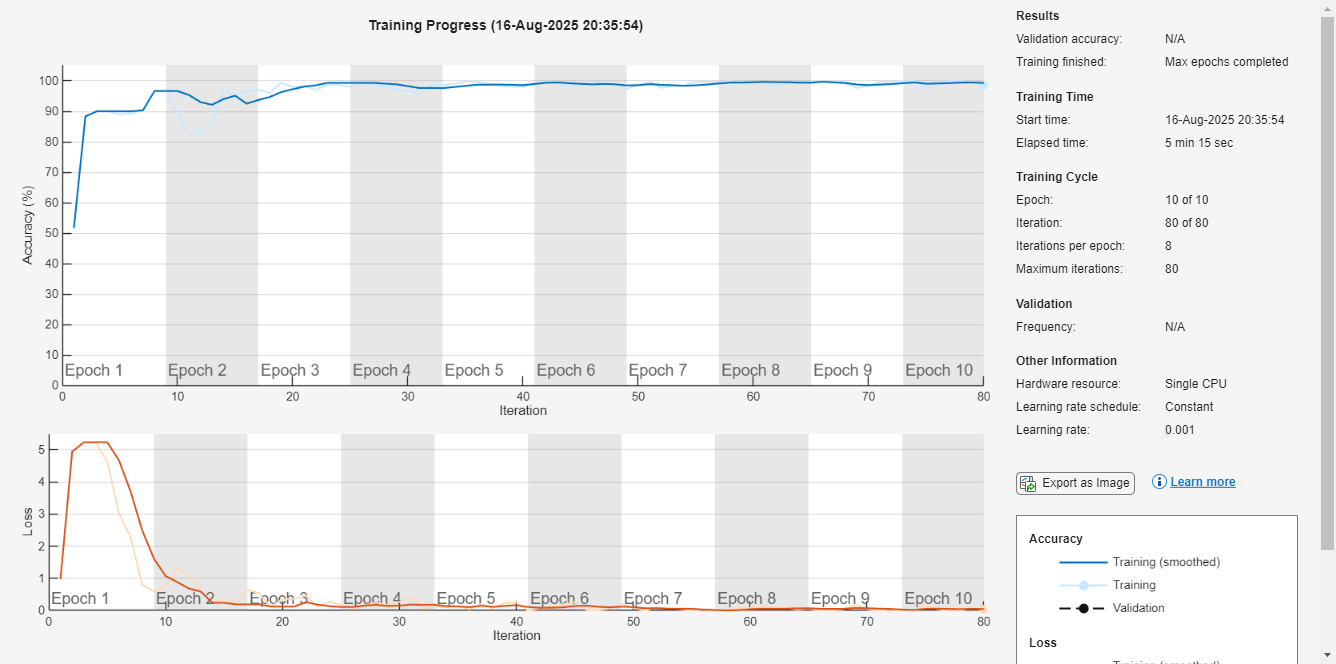

net = trainNetwork(augTrain, layers, options);

## Schätzung

% Testen des Neuronalen Netzes
trainPreds = classify(net,augTrain);
testPreds = classify(net,augVal);

## Evaluierung

% Evaluierung des Modelles
confMat = confusionmat(imdsTrain.Labels, trainPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 99.66%


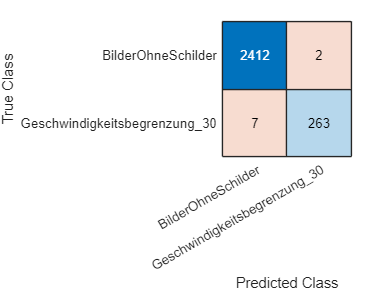

confusionchart(imdsTrain.Labels, trainPreds);

confMat = confusionmat(imdsValidation.Labels, testPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 98.51%


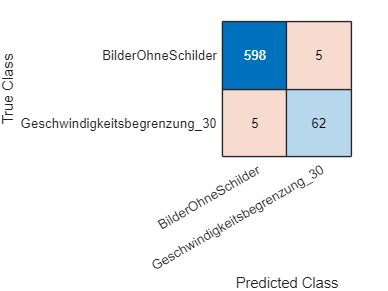

confusionchart(imdsValidation.Labels, testPreds);